# Range-Doppler Response Using Matched Filter

Compute the range-doppler response of a pulsed radar signal using a matched filter.

Load data for a pulsed radar signal. The signal includes three target returns. Two targets are approximately 2000 m away, while the third is approximately 3500 m away. In addition, two of the targets are stationary relative to the radar. The third is moving away from the radar at about 100 m/s.

load RangeDopplerExampleData;

Create a range-Doppler response object.

response = phased.RangeDopplerResponse('DopplerFFTLengthSource','Property', ...
   'DopplerFFTLength',RangeDopplerEx_MF_NFFTDOP, ...
   'SampleRate',RangeDopplerEx_MF_Fs,'DopplerOutput','Speed', ...
   'OperatingFrequency',RangeDopplerEx_MF_Fc);

Calculate the range-Doppler response.

[resp,rng_grid,dop_grid] = response(RangeDopplerEx_MF_X, ...
    RangeDopplerEx_MF_Coeff);

Plot the range-Doppler response.

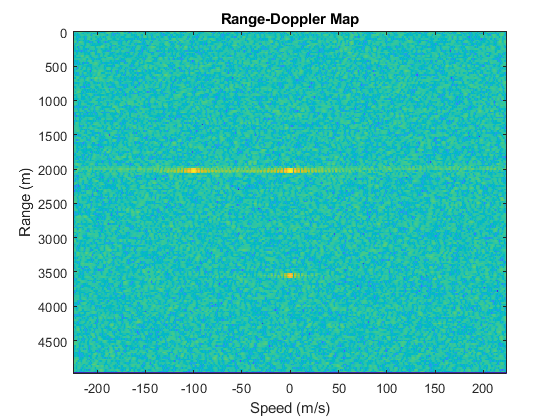

imagesc(dop_grid,rng_grid,mag2db(abs(resp)));
xlabel('Speed (m/s)');
ylabel('Range (m)');
title('Range-Doppler Map');

*Copyright 2012 The MathWorks, Inc.*